y = load('data.csv');
y = y';
x = 0:1/199999:1;
x = x';
N = size(y,1);
idx = randperm(N);
PD = 0.8;
tx = x(idx(1:round(N*PD)),:);
vx = x(idx(round(N*PD)+1:end),:);
ty = y(idx(1:round(N*PD)),:);
vy = y(idx(round(N*PD)+1:end),:);

%tx = xtrain;
%ty = ytrain';
%vx = xtest;
%vy = ytest';
tx = tx';
vx = vx';
ty = ty';
vy =vy';

plotData(tx,ty)
hold on
for i = 7:13
    p = polyfit(tx,ty,i);
    y1 = polyval(p,tx);
    tsse = sum((ty-y1).^2);
    ya = sum(ty)/length(ty);
    tsst = sum((ty-ya).^2);
    tR2 = 100*(1-(tsse/tsst))
    tmse = tsse/length(ty)
    y2 = polyval(p,vx);
    sse = sum((vy-y2).^2);
    yav = sum(vy)/length(vy);
    sst = sum((vy-yav).^2);
    R2 = 100*(1-(sse/sst))
    mse = sse/length(vy)
    plot(vx,y2,'.',"LineWidth",2);
    hold on        
end

tR2 = 79.7052

tmse = 1.0408

R2 = 79.6063

mse = 1.0425

tR2 = 98.7712

tmse = 0.0630

R2 = 98.7492

mse = 0.0639

tR2 = 99.4377

tmse = 0.0288

R2 = 99.4341

mse = 0.0289

tR2 = 99.7713

tmse = 0.0117

R2 = 99.7735

mse = 0.0116

tR2 = 99.8001

tmse = 0.0102

R2 = 99.8011

mse = 0.0102

tR2 = 99.8791

tmse = 0.0062

R2 = 99.8790

mse = 0.0062

tR2 = 99.8877

tmse = 0.0058

R2 = 99.8877

mse = 0.0057

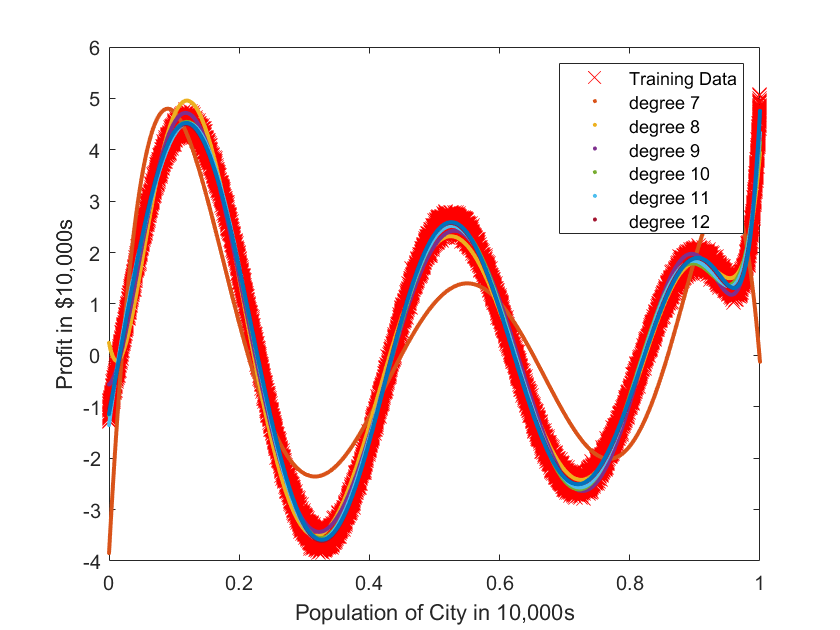

legend('Training Data', 'degree 7', 'degree 8', 'degree 9', 'degree 10', 'degree 11', 'degree 12')